# Initializing

% Initializing path of HDF5 file
clear all;
rootpath= initialize_root_path; 
fileNameStr = [rootpath,'energy-height-conversion/PFISR_Energy_Spectra/Data/DataFile_2008_1.h5'];

% Initializing GeoData class
% initialize_geodata([rootpath,'energy-height-conversion\GeoDataMATLAB\']);


## Extracting data

pfisrGD = GeoData(@readMadhdf5,fileNameStr,{'popl'});

PFISR data



% Change the log electron density to linear density
antilog = @(ex,base)(base.^ex);
pfisrGD.changedata('popl','ne',antilog,{10});
% pfisrGD.interpolate(pfisrGD.dataloc,'Cartesian','natural');


## Converting coordinates to Geodetic

data.electronDensity = pfisrGD.data.ne;
data.time = unix_to_matlab_time(pfisrGD.times(:,1));
nBeams=26;
nData = length(data.electronDensity(:,1));
for itime=1:1:length(data.time)
    for iBeam = 1:1:26
        data.electronDensity(iBeam:nBeams:nData,itime)...
            = interp_nans(data.electronDensity(iBeam:nBeams:nData,itime));
    end
end

% [cartCoords(:,1),cartCoords(:,2),cartCoords(:,3)] = sph2cart(degtorad(pfisrGD.dataloc(:,2)),degtorad(pfisrGD.dataloc(:,3)),pfisrGD.dataloc(:,1));
az=pfisrGD.dataloc(:,2);
elev=pfisrGD.dataloc(:,3);
slant=pfisrGD.dataloc(:,1);
[yNorth, xEast, zDown] = aer2ned(az,elev,slant);
%figure; plot(xEast(1:26),yNorth(1:26),'o');
lat0 = 65.126;
lon0 = -147.47;
height = 0.689;
[geodeticCoords(:,1),geodeticCoords(:,2),geodeticCoords(:,3)] = ned2geodetic(yNorth,xEast,zDown,lat0,lon0,height,wgs84Ellipsoid('km'));

## Plot 2D map

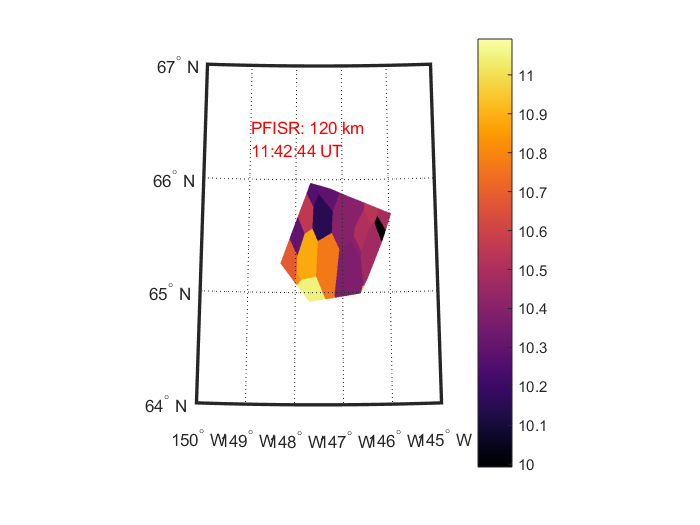

thisTime = '26-Mar-2008 11:43';
[timeNo] = find_time(data.time, thisTime);
figure;
plot_2D_density_slice_geodetic...
    (data, geodeticCoords, timeNo, 120, true);
colormap(inferno);
colorbar;

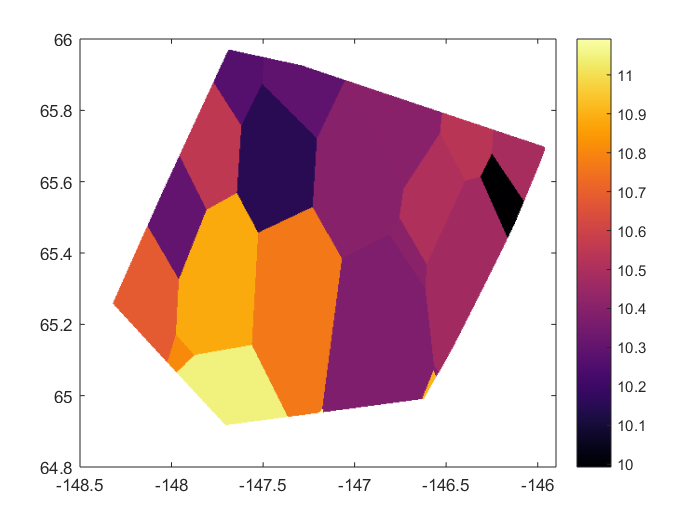

figure;
plot_2D_density_slice_geodetic...
    (data, geodeticCoords, timeNo, 120, false, [64.8,66], [-148.5,-145.9]);
colormap(inferno);
colorbar;